 This is a model identification exercise for Clemson Clearpath Husky. The model is to be of moderate fidelity such that it can be used for Husky control tasks. Following papers were refered for boot strapping.

[1] Yu, W., Chuy, O., Collins, E., & Hollis, P. (2009). *Dynamic Modeling of a Skid-Steered Wheeled Vehicle with Experimental Verification*. [https://doi.org/10.1109/IROS.2009.5354381](https://doi.org/10.1109/IROS.2009.5354381)

[2] Kozłowski, K., & Pazderski, D. (2004). Modeling and Control of a 4-wheel Skid-steering Mobile Robot. In *Modeling and Control of a 4-wheel Skid-steering Mobile Robot* (Vol. 14, Issue 4, pp. 477–496).

[3] Caracciolo, L., De Luca, A., & Iannitti, S. (1999). Trajectory tracking control of a four-wheel differentially driven mobile robot. *Proceedings - IEEE International Conference on Robotics and Automation*, *4*(May), 2632–2638. [https://doi.org/10.1109/robot.1999.773994](https://doi.org/10.1109/robot.1999.773994)

Extract Messages from relvant ROSBAG

clc
clear

bag = rosbag('temp\2023-02-16-15-51-57.bag');
clc

%% Parse Bag for relevant topics 

piksi.navast_bf = select(bag,'Topic','/piksi_multi_position/navsatfix_best_fix'); %These topics are in WGS
% (Latitude,Deg Longitude,Deg Altitude,m)
%piksi.navast_bf_hd = select(bag,'Topic','/piksi_multi_heading/navsatfix_best_fix');
%piksi.enu_pose_bf = select(bag,'Topic','/piksi_multi_position/enu_pose_best_fix'); %These topics are in ENU (m m m)
gx5.imu_data = select(bag,'Topic','/gx5/imu/data'); % IMU data from gx5
gx5.mag = select(bag,'Topic','/gx5/mag'); % Magnetometer data from gx5
husky.command_vel = select(bag,'Topic','/husky_velocity_controller/cmd_vel');
husky.status = select(bag,'Topic','/status'); % internal status information (motor currents)
husky.joint_states = select(bag,'Topic','/joint_states'); % Wheel encoder information
%}

msgStructs.piksi.navast_bf = readMessages(piksi.navast_bf,'DataFormat','struct');
%msgStructs.piksi.navast_bf_hd = readMessages(piksi.navast_bf_hd,'DataFormat','struct');
%msgStructs.piksi.enu_pose_bf = readMessages(piksi.enu_pose_bf,'DataFormat','struct');
msgStructs.gx5.imu_data = readMessages(gx5.imu_data,'DataFormat','struct');
msgStructs.gx5.mag = readMessages(gx5.mag,'DataFormat','struct');
msgStructs.cmd_vel = readMessages(husky.command_vel,'DataFormat','struct');
msgStructs.status = readMessages(husky.status,'DataFormat','struct');
msgStructs.joint_states = readMessages(husky.joint_states,'DataFormat','struct');
%}

clc

%save('data.mat')
%load('data.mat')


**Kinematic Model** : (from [1])

$\alpha$ is a parameter that needs to be experimentally identified. It is dependent on friction. $\omega$ can be calculated from wheel odometry. $v_y \;\textrm{and}\;\overset{\ldotp }{\phi}$ can be estimated from the IMU readings. $B\;\textrm{and}\;r$ are geometric constants. Instead of getting jusy one value for alpha, the idea is to create a look up table for various values of $v_y \;\textrm{and}\;\overset{\ldotp }{\phi}$

This model will then be used for RL training.

From the IMU data, find all available v and phi_dotThese linear velocities and angular velocities are realized values and different from the command velocities

for i =1:length(msgStructs.gx5.imu_data)
    lin_acc(i) = msgStructs.gx5.imu_data{i, 1}.LinearAcceleration.X;
    mean_lin_acc = sum(lin_acc)/length(lin_acc);
    ang_vel(i) = msgStructs.gx5.imu_data{i, 1}.AngularVelocity.Z;
end

% compute frequency of IMU messages
freq.IMU = (gx5.imu_data.EndTime  -gx5.imu_data.StartTime)/gx5.imu_data.NumMessages; % value in s

lin_vel(1) =0;
for i = 1:length(lin_acc)
    lin_vel(i+1) = lin_vel(i)+lin_acc(i)*1e-4;
end


Command velocity (V and w to right and left wheel velocity conversion)

if angular velocity is positive, the vehicle is turning left, so w_l >

w_r and vice versa

wheel radius r = 0.1650 m

track width B = 0.555 m

r = 0.1650;
B = 0.555;

freq.cmd_vel = (husky.command_vel.EndTime-husky.command_vel.StartTime)/husky.command_vel.NumMessages;

for i = 1:length(msgStructs.cmd_vel)
    V(i) = msgStructs.cmd_vel{i, 1}.Linear.X; 
    omega(i) = msgStructs.cmd_vel{i, 1}.Angular.Z;
end

w_r = (0.8*V/r) + (B*omega)/(2*r);
w_l = (0.8*V/r) - (B*omega)/(2*r);

% windowSize = 50; 
% b = (1/windowSize)*ones(1,windowSize);
% a = 1;
% 
% y1 = filter(b,a,w_r);
% y2 = filter(b,a,w_l);
% 
% w_r = y1;
% w_l = y2;





From the kinematic model:

[v_hat phi_dot_hat]' = A * [w_r w_l]';

where A = [r/2 r/2; -r/alpha*B r/alpha*B]

alpha is identification param and B is track width


% for initialization guess assume alpha is 1.8
alpha = 2;

A = [r/2 r/2;-r/(alpha*B) r/(alpha*B)];

[vel_hat] = A*[w_r;w_l];

% vel_hat(1,1)=0;
% for i=1:length(vel_hat)
%     vel_hat(1,i+1) = vel_hat(1,i) + (1/length(vel_hat))*1;
% end


%% Four wheel variation
alpha_f = 2;
A_four = [r/4 r/4 r/4 r/4;-r/(2*alpha_f*B) -r/(2*alpha_f*B) r/(2*alpha_f*B) r/(2*alpha_f*B)];

w_rf=w_r;
w_rr=w_r;
w_lf=w_l;
w_lr=w_l;

[vel_hat_f] = A_four*[w_rf;w_rr;w_lf;w_lr];
% vel_hat_f(1,1)=0;
% for i=1:length(vel_hat_f)
%     vel_hat_f(1,i+1) = vel_hat_f(1,i) + (1/length(vel_hat_f))*1;
% end


%% Position from both the velocities

% Position from model
%x_hat = x_hat(i)
%initial positions x0, y0, yaw0 =[0 0 0]

x_hat(1) = 0;
y_hat(1) = 0;
yaw_hat(1) = -pi/3;
x_hat_f(1) =0;
y_hat_f(1) = 0;
yaw_hat_f(1) = -pi/3;
sim_time = length(vel_hat);
sim_time2 = length(vel_hat_f);
dt = 0.01;

for i = 1:sim_time
    x_hat(i+1) = x_hat(i) + vel_hat(1,i)*cos(yaw_hat(i))*dt ;
    y_hat(i+1) = y_hat(i) + vel_hat(1,i)*sin(yaw_hat(i))*dt ;
    yaw_hat(i+1) = yaw_hat(i)+ vel_hat(2,i)*dt;
end

for i = 1:sim_time2
    x_hat_f(i+1) = x_hat_f(i) + vel_hat_f(1,i)*cos(yaw_hat_f(i))*dt ;
    y_hat_f(i+1) = y_hat_f(i) + vel_hat_f(1,i)*sin(yaw_hat_f(i))*dt ;
    yaw_hat_f(i+1) = yaw_hat_f(i)+ vel_hat_f(2,i)*dt;
end



Figures for validation

- Commanded Velocities

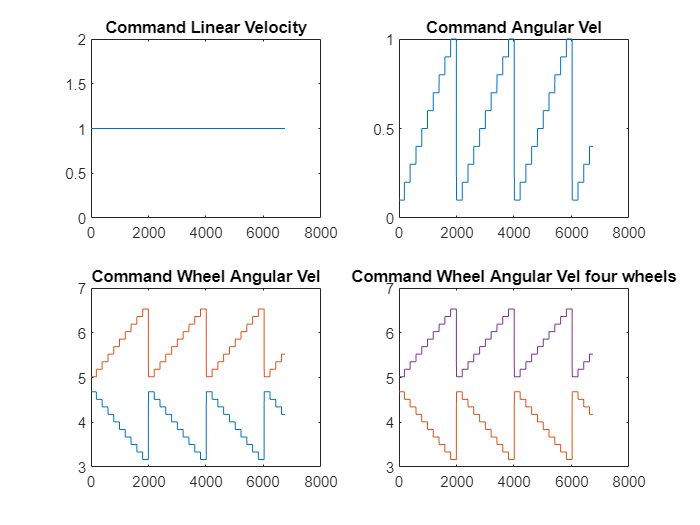

%% compare predicted and realized velocity profiles
figure

subplot(2,2,1);
plot(V)
title('Command Linear Velocity')

subplot(2,2,2);
plot(omega)
title('Command Angular Vel')

subplot(2,2,3);
plot(w_l)
hold on
plot(w_r)
title('Command Wheel Angular Vel')

subplot(2,2,4);
plot(w_lr)
hold on
plot(w_lf)
hold on
plot(w_rf)
hold on
plot(w_rr)
title('Command Wheel Angular Vel four wheels')

2. Realized Velocities : Model and IMU

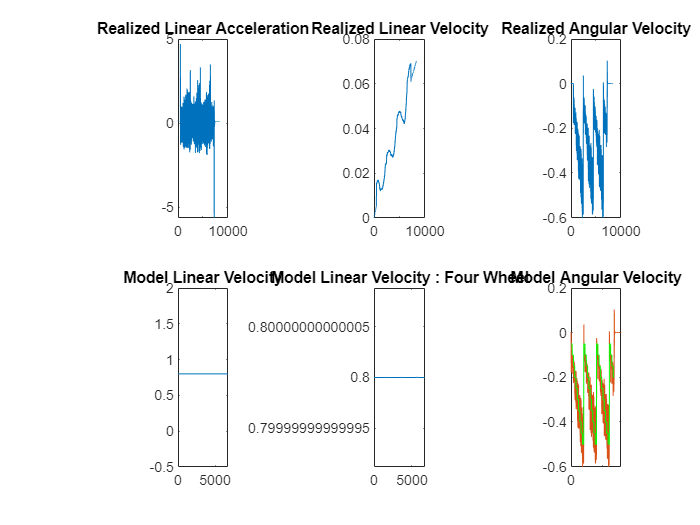

figure
subplot(2,3,1)
plot(lin_acc)
title('Realized Linear Acceleration')

subplot(2,3,2)
plot(lin_vel(1:end-1))
title('Realized Linear Velocity')

subplot(2,3,3)
plot(ang_vel)
title('Realized Angular Velocity')

subplot(2,3,4)
plot(vel_hat(1,:))
title('Model Linear Velocity')

subplot(2,3,5)
plot(vel_hat_f(1,:))
title('Model Linear Velocity : Four Wheel')


subplot(2,3,6)
plot(vel_hat(2,:),'-k')
title('Model Angular Velocity')
hold on
plot(ang_vel(455:end))
hold on
plot(vel_hat_f(2,:),'-g')

figure
%plot(vel_hat(2,:),'-k')
title('Angular Velocity')
hold on
plot(ang_vel(455:end))
hold on
plot(vel_hat_f(2,:),'-r')
legend('IMU derived','Model Predicted')

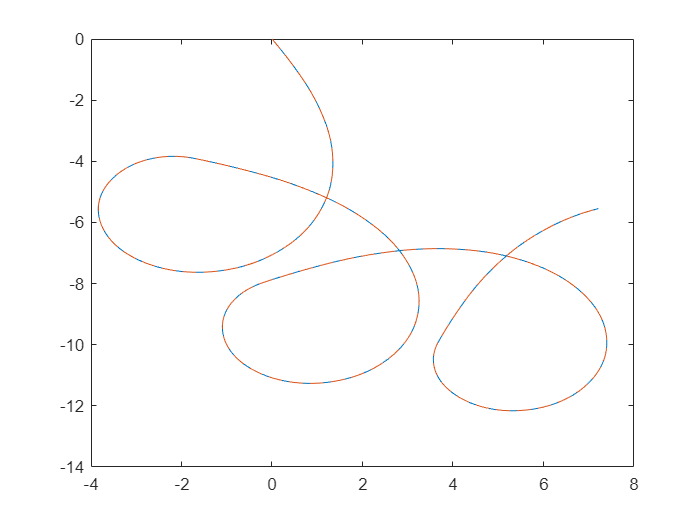

figure
plot(x_hat,y_hat)
hold on
plot(x_hat_f,y_hat_f,'--')

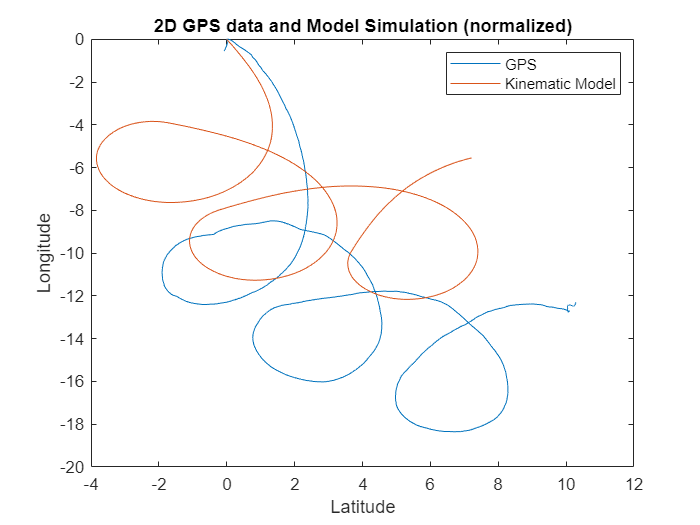


sensor.navsat_bf = [msgStructs.piksi.navast_bf{:,1}];
gps_lat = [sensor.navsat_bf.Latitude];
gps_long = [sensor.navsat_bf.Longitude];
gps_lat_shifted = gps_lat - gps_lat(50);
gps_long_shifted =gps_long-gps_long(50);

% figure
% plot(gps_lat, gps_long);

% figure
% plot(gps_lat_shifted*1e5, gps_long_shifted*1e5)

%%

figure
plot(gps_lat_shifted*1e5, gps_long_shifted*1e5)
hold on
%plot(x_hat,y_hat)
hold on
plot(x_hat_f,y_hat_f)
legend('GPS','Kinematic Model')
title('2D GPS data and Model Simulation (normalized)')
xlabel('Latitude')
ylabel('Longitude')

%{
waypoints_wgs84=[sensor.navsat_bf.Latitude;sensor.navsat_bf.Longitude;sensor.navsat_bf.Altitude]';
wgs84 = wgs84Ellipsoid;

% these are provided by eth_zurich who made the ros drivers for piksi_multi
lat0 = 47.81;
lon0 = 8.51;
h0 = 565.7;

format shortG
[xEast,yNorth,zUp] = geodetic2enu(waypoints_wgs84(:,1),waypoints_wgs84(:,2),waypoints_wgs84(:,3),lat0,lon0,h0,wgs84);

waypoints_enu =[xEast,yNorth,zUp];

% figure
% plot(waypoints_wgs84(:,1),waypoints_wgs84(:,2))
% %hold on
% %plot(waypoints_wgs84(1,2),waypoints_wgs84(1,1),'o')
% title('wgs84')
% xlabel('Latitudes')
% ylabel('Longitudes')

figure
plot(waypoints_enu(:,1),waypoints_enu(:,2))
hold on
plot(waypoints_enu(1,1),waypoints_enu(1,2),'o')
title('enu')
xlabel('East (-->): m')
ylabel('North (-->): m')
% for now, we assume we initialize the robot as the number one enu waypoint

% x_local = 0  y_local = 0;
% x_enu = enu_waypoints(1,1)  x_enu = enu_waypoints(1,2)
% X_local = Map * X_enu;
%X_local = [waypoints_enu(1,1);waypoints_enu(1,2)].*ones(2,16);
X_local = [waypoints_enu(1,1);waypoints_enu(1,2)].*ones(2,837);
X_local = X_local-[waypoints_enu(:,1:2)]'; % This is translation of the coordintate frame
theta = 3*pi/2;
X_local = [cos(theta) sin(theta);-1*sin(theta) cos(theta)]*X_local; % This is rotation of the coordinate frame

figure
plot(-1*X_local(1,1:505),-1*X_local(2,1:505),'*')
hold on
plot(-1*X_local(1,1),-1*X_local(2,1),'o')
title('local')
xlabel('m')
ylabel('m')
%}